# Solve DAE for cart-pole system

Example from documentation:

- [https://www.mathworks.com/help/symbolic/solve-differential-algebraic-equations.html](https://www.mathworks.com/help/symbolic/solve-differential-algebraic-equations.html)

Equations and diagram below from:

- R. V. Florian, 2007, Correct equations for the dynamics of the cart-pole system

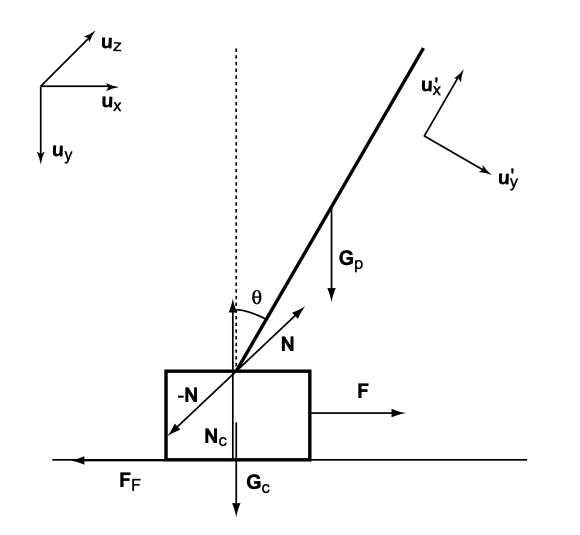

State variables

- Horizontal position of pendulum (from left) $x\left(t\right)$

- Horizontal velocity of cart $\dot{x} \left(t\right)$

- Angle of pole (clockwise) $\theta \left(t\right)$

- Angular rotation of pole $\dot{\;\theta \;} \left(t\right)$

Other variables

- Downwards force on track from cart $N_c \left(t\right)$

- Frictional force exerted on cart by track $F_F \left(t\right)$

- Force exerted on cart by pole (and vice versa) $N\left(t\right)$

Potential input variables

- Horizontal force on cart $F\left(t\right)$

Parameters

- Cart mass $m_c$

- Pole mass $m_p$

- Pendulum length $l$

- Acceleration due to gravity $g$

- Coefficient of friction for cart and track $\mu_c$

- Coefficient of friction for pole and cart joint $\mu_p$

DAE system of equations


$$\begin{array}{l}
N_c =\left(m_c +m_p \right)g-m_p l\left(\ddot{\theta} \;\sin \theta +{\dot{\theta} }^2 \;\cos \theta \right)\\
\ddot{\theta} =\frac{g\;\sin \theta +\cos \theta \left\lbrace \frac{-F-m_p l{\dot{\theta} }^2 \left(\sin \theta +\mu_c \;\textrm{sgn}\left(N_c \dot{x} \right)\cos \theta \right)}{m_c +m_p }+\mu_c g\;\textrm{sgn}\left(N_c \dot{x} \right)\right\rbrace -\frac{\mu_p \dot{\theta} }{m_p l}}{l\left\lbrace \frac{4}{3}-\frac{m_p \cos \theta }{m_c +m_p }\left(\cos \theta -\mu_c \;\textrm{sgn}\left(N_c \dot{x} \right)\right)\right\rbrace }\\
\ddot{x} =\frac{F+m_p l\left({\dot{\theta} }^2 \;\sin \theta -\ddot{\theta} \;\cos \theta \right)-\mu_c N_c \textrm{sgn}\left(N_c \dot{x} \right)}{m_c +m_p }
\end{array}$$


clear variables

syms x(t) theta(t) Nc(t) F mc mp l g muc mup

eqn1 = 1000 * Nc == (mc + mp) * g - mp * l * (diff(theta(t), 2) * sin(theta(t)) + diff(theta(t))^2 * cos(theta(t)))

$$eqn1(t) = 1000\,\mathrm{Nc}\left(t\right)=g\,\left(\mathrm{mc}+\mathrm{mp}\right)-l\,\mathrm{mp}\,\left(\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)$$

eqn2 = diff(theta(t), 2) == ...
    (g * sin(theta(t)) + cos(theta(t)) * ( ...
        (-F - mp * l * diff(theta(t))^2 * (sin(theta(t)) + muc * sign(Nc * diff(x(t))) * cos(theta(t))) ...
     ) / (mc + mp) + muc * g * sign(Nc * diff(x(t)) )) - mup * diff(theta(t)) / (mp * l) ) ...
    / (l * (4/3 - mp * cos(theta(t)) / (mc + mp) * (cos(theta(t)) - muc * sign(Nc * diff(x(t))))))

$$eqn2(t) = \begin{array}{l} \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{\cos\left(\theta \left(t\right)\right)\,\left(\frac{F+l\,\mathrm{mp}\,\left(\sin\left(\theta \left(t\right)\right)+\mathrm{muc}\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{\mathrm{mc}+\mathrm{mp}}-g\,\mathrm{muc}\,\sigma_{1}\right)-g\,\sin\left(\theta \left(t\right)\right)+\frac{\mathrm{mup}\,\frac{\partial }{\partial t}\theta \left(t\right)}{l\,\mathrm{mp}}}{l\,\left(\frac{\mathrm{mp}\,\cos\left(\theta \left(t\right)\right)\,\left(\cos\left(\theta \left(t\right)\right)-\mathrm{muc}\,\sigma_{1}\right)}{\mathrm{mc}+\mathrm{mp}}-1.3333\right)}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\,\frac{\partial }{\partial t}x\left(t\right)\right) \end{array}$$

eqn3 = diff(x(t), 2) == ...
    (F + mp * l * (diff(theta(t))^2 * sin(theta(t)) - diff(theta(t), 2) * cos(theta(t))) ...
     - muc * 1000 * Nc * sign(Nc * diff(x(t)))) ...
    / (mc + mp)

$$eqn3(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\frac{F+l\,\mathrm{mp}\,\left(\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\right)-1000\,\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\,\frac{\partial }{\partial t}x\left(t\right)\right)\,\mathrm{Nc}\left(t\right)}{\mathrm{mc}+\mathrm{mp}}$$

eqns = [eqn1 eqn2 eqn3];
vars = [x(t); theta(t); Nc(t)];
origVars = length(vars)

origVars = 3

Check Incidence of Variables

M = incidenceMatrix(eqns, vars)

M =      0     1     1
     1     1     1
     1     1     1


Reduce Differential Order

[eqns, vars] = reduceDifferentialOrder(eqns, vars)

$$eqns = \begin{array}{l} \left(\begin{array}{c} 1000\,\mathrm{Nc}\left(t\right)-g\,\left(\mathrm{mc}+\mathrm{mp}\right)+l\,\mathrm{mp}\,\left(\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{Dthetat}\left(t\right)+\cos\left(\theta \left(t\right)\right)\,{\mathrm{Dthetat}\left(t\right)}^{2}\right)\\ \frac{\partial }{\partial t}\mathrm{Dthetat}\left(t\right)-\frac{\cos\left(\theta \left(t\right)\right)\,\left(\frac{l\,\mathrm{mp}\,\left(\sin\left(\theta \left(t\right)\right)+\mathrm{muc}\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}\right)\,{\mathrm{Dthetat}\left(t\right)}^{2}+F}{\mathrm{mc}+\mathrm{mp}}-g\,\mathrm{muc}\,\sigma_{1}\right)-g\,\sin\left(\theta \left(t\right)\right)+\frac{\mathrm{mup}\,\mathrm{Dthetat}\left(t\right)}{l\,\mathrm{mp}}}{l\,\left(\frac{\mathrm{mp}\,\cos\left(\theta \left(t\right)\right)\,\left(\cos\left(\theta \left(t\right)\right)-\mathrm{muc}\,\sigma_{1}\right)}{\mathrm{mc}+\mathrm{mp}}-1.3333\right)}\\ \frac{l\,\mathrm{mp}\,\left(\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{Dthetat}\left(t\right)-\sin\left(\theta \left(t\right)\right)\,{\mathrm{Dthetat}\left(t\right)}^{2}\right)-F+1000\,\mathrm{muc}\,\sigma_{1}\,\mathrm{Nc}\left(t\right)}{\mathrm{mc}+\mathrm{mp}}+\frac{\partial }{\partial t}\mathrm{Dxt}\left(t\right)\\ \mathrm{Dxt}\left(t\right)-\frac{\partial }{\partial t}x\left(t\right)\\ \mathrm{Dthetat}\left(t\right)-\frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{sign}\left(\mathrm{Dxt}\left(t\right)\,\mathrm{Nc}\left(t\right)\right) \end{array}$$

$$vars = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ \mathrm{Nc}\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

Check Differential Index of System

if ~isLowIndexDAE(eqns, vars)
    disp("Reducing Differential Index...")
    % Reduce Differential Index with reduceDAEIndex
    [DAEs, DAEvars] = reduceDAEIndex(eqns, vars)
    % Eliminate redundant equations and variables
    [DAEs, DAEvars] = reduceRedundancies(DAEs, DAEvars)
    % Check the differential index of the new system
    assert(isLowIndexDAE(DAEs, DAEvars))
else
    DAEs = eqns;
    DAEvars = vars;
end

### Convert DAE system to MATLAB function

pDAEs = symvar(DAEs);
pDAEvars = symvar(DAEvars);
extraParams = setdiff(pDAEs, pDAEvars)

$$extraParams = \left(\begin{array}{ccccccc} F & g & l & \mathrm{mc} & \mathrm{mp} & \mathrm{muc} & \mathrm{mup} \end{array}\right)$$

Create the function handle

f = daeFunction(DAEs, DAEvars, F, g, l, mc, mp, muc, mup);

### Set parameter values

F = 0.1;
g = 9.81;
l = 1;
mc = 5

mc = 5

mp = 2;
muc = 0.5;
mup = 0.5;

Create function for ode15i

F_DAE = @(t, Y, YP) f(t, Y, YP, F, g, l, mc, mp, muc, mup);

### Find initial condition

DAEvars

$$DAEvars = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ \mathrm{Nc}\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

Note that `Dxt(t)`, `Dthetat(t)`, ... etc. are the first derivatives of `x(t)` ... etc.

Provide an estimate of the initial condition

% Variables
% 1 degrees = 0.0172
x0est = [0; pi/12; 0.001*9.81*5; 0; 0];
% Their derivatives
xp0est = [0; 0; 0; 0; 0];

Set tolerances and do numerical search.

opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_X0 = [1 1 0 1 1]';
FIXED_YP0 = [0 0 0 0 0]';
[x0, xp0] = decic(F_DAE, 0, x0est, FIXED_X0, xp0est, FIXED_YP0, opt)

x0 =          0
    0.2618
    0.0674
         0
         0


xp0 =          0
         0
         0
   -0.6390
    2.3672


### Solve DAEs Using ode15i

[tSol, xSol] = ode15i(F_DAE, [0 0.5], x0, xp0, opt);

Plot solution

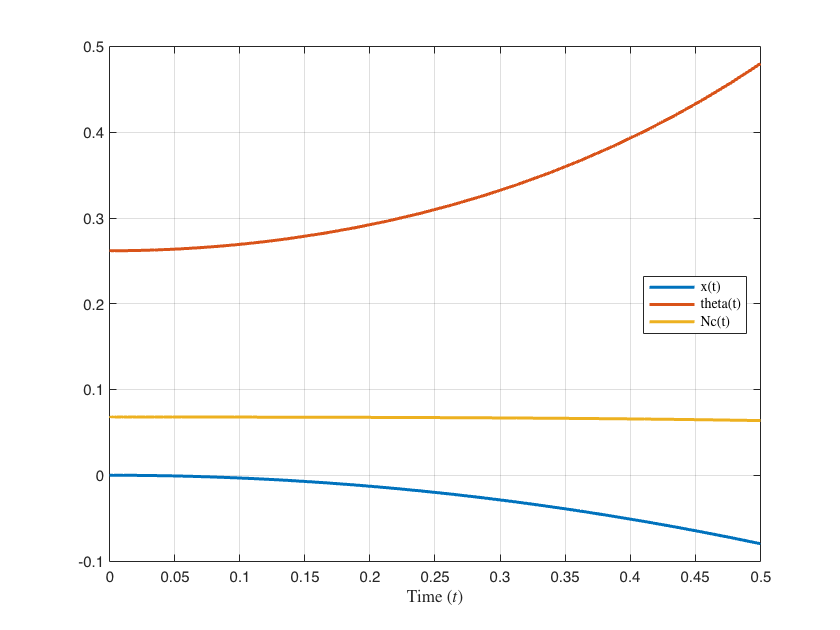

plot(tSol, xSol(:, 1:origVars), 'LineWidth', 2)
xlabel("Time ($t$)", 'Interpreter', 'latex')
labels = arrayfun(@(i) char(DAEvars(i)), 1:origVars, 'UniformOutput', false);
legend(labels, 'Location', 'Best', 'Interpreter', 'latex')
grid on